% Тренировка Нейронной сети
% Исходные данные:
input_nodes = 784; % Так как изображение 784 пикселя
hidden_nodes = 200; % Просто взято с потолка (уточняется после тренироваки и результатов работы Нейроннйо сети)
output_nodes = 10; % Определяется кол-вом маркеров (в случае обработки изображений на выходе у нас числа от 0 до 9 (10 штук))

learning_rate = 0.2;

% Создание 
n = neuralNetwork(input_nodes,hidden_nodes,output_nodes,learning_rate);


% Загрузка данных для тестирования
mnist_train = MNIST_load('testdata\mnist_train.csv', 1, 60000);
[xtrain,ytrain] = size(mnist_train); % x - кол-во тестовых данных данных, y - длина тестовых данных
mnist_to_train = zeros(xtrain,ytrain-1);
% mnist_prep_data = zeros(28,28,xtrain);
% for i = 1:xtrain
%     mnist_prep_data(:,:,i) = reshape(mnist_train(i,2:ytrain),[28,28])';
% end

% Подготовка данных для Нейронной сети
for i = 1:xtrain
    %mnist_prep_data(:,:,i) = ((mnist_prep_data(:,:,i) / 255.0)*0.99) + 0.01;
    mnist_to_train(i,1:(ytrain-1)) = ((mnist_train(i,2:ytrain) / 255.0)*0.99) + 0.01;
end

% Подготовка выходного массива Нейронной сети
onodes = 10; % Кол-во выходных узлов
%targets = zeros(onodes,1) + 0.01;
%targets(int32(mnist_train(1))+1) = 0.99;


    % Тренировка Нейронной сети
epochs = 5; % Количество прогонов обучения.
for ep = 1: epochs
    for i = 1:xtrain
        targets = zeros(onodes,1) + 0.01;
        targets(int32(mnist_train(i,1))+1) = 0.99;
        
        n.train(mnist_to_train(i,1:(ytrain-1))',targets);
    end
end

% Загрузка данных для тестирования

mnist_test = MNIST_load('testdata\mnist_test.csv', 1, 10000);
[xtest,ytest] = size(mnist_test); % x - кол-во тестовых данных данных, y - длина тестовых данных
mnist_test_img_data = zeros(28,28,xtest);
for i = 1:xtest
    mnist_test_img_data(:,:,i) = reshape(mnist_test(i,2:ytest),[28,28])';
end
conv_indicate_numbers

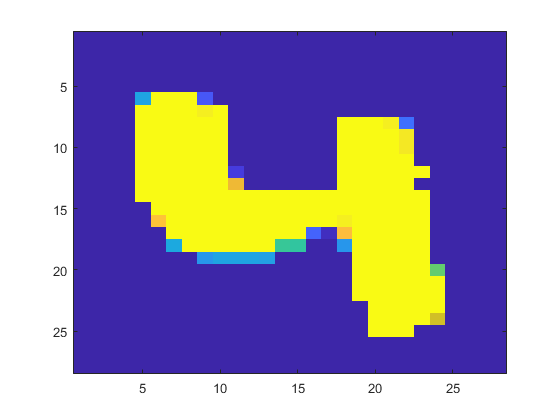

% Тестирование Нейронной сети
index_image = 476;

if index_image < 1
    index_image = 1;
elseif index_image > 10000
    index_image = 10000;
end
image(mnist_test_img_data(:,:,index_image));

%colormap('gray');
res = n.query(((mnist_test(index_image,2:ytest)')/255.0 * 0.99) + 0.01)

res =     0.0088
    0.0041
    0.0006
    0.0007
    0.9992
    0.0201
    0.0218
    0.0272
    0.0047
    0.0012


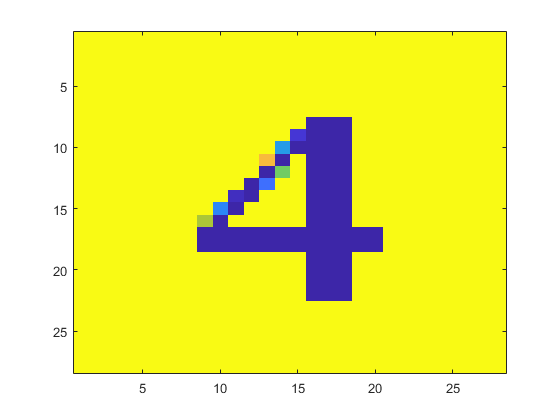

num = (find(res == max(res),1));

image(reshape(elite_numbers(num,2:end),28,28))

% Проверка Нейронной сети на всем диапазоне тестовых данных
scorecard = [];
for i = 1:xtest
    correct_label = mnist_test(i,1);
    label = n.query(((mnist_test(i,2:ytest)')/255.0 * 0.99) + 0.01);
    recognize_num = (find(label == max(label),1)-1);
    if recognize_num == correct_label
        scorecard = [scorecard 1];
    else
        scorecard = [scorecard 0];
    end
end
% Расчет эффективности работы Нейронной сети
[xscore,yscore] = size(scorecard);
disp('Эффективность Нейронной сети, в %');

Эффективность Нейронной сети, в %


disp((sum(scorecard)/yscore)*100);

   96.9400




% Вывод на экран маркеров ответов Нейронной сети и эффективности
% disp('Маркеры ответов');
% disp(0:9);
% disp(scorecard);
